%% Read Input
data = readmatrix('EMG_example_20s_2000Hz-2022.csv');
signal1 = data(:,1);
signal2 = data(:,2);

f = 2000; % Hz
total_time = 20; % seconds
time = linspace(0,total_time,f*total_time+1)'; % '+1' included to make time same dimension as the signal

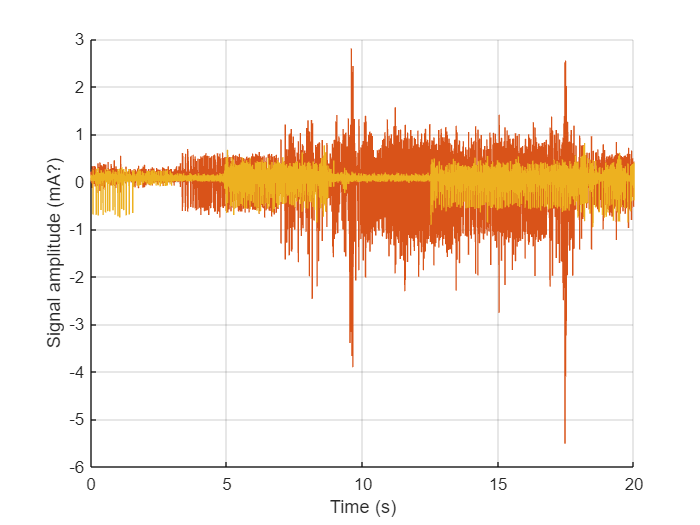

hold on
plot(time,signal1)
plot(time,signal2)
xlabel("Time (s)"); ylabel('Signal amplitude (mA?)');
hold off

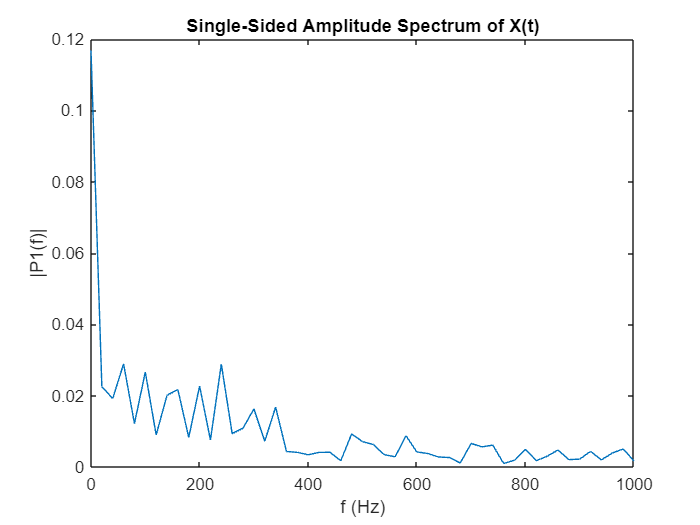

trunc1 = signal1(1:100,:);
Y = fft(trunc1);
L = length(trunc1);
Fs = 2000;
T = 1/Fs;

P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
plot(f,P1) 
title("Single-Sided Amplitude Spectrum of X(t)")
xlabel("f (Hz)")
ylabel("|P1(f)|")

Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 1500;             % Length of signal
t = (0:L-1)*T;        % Time vector